# Milestone 2 - Perception

## Yusra Shahid

## **Task Definition:**

**Required Output:** The perception pipeline is designed to detect and estimate the pose of a single red box located within the robot’s workspace. The object being perceived is a rigid cuboidal block of known dimensions. The pipeline estimates the block’s 3D position and its orientation about the vertical (z) axis, which together define the block’s pose. Since the block rests on a planar surface, only the yaw angle (rotation about z-axis) is considered relevant. The output pose is expressed in the camera frame, which serves as the world reference frame in this system.

**Camera: **An overhead-mounted Intel RealSense SR305 RGB-D camera is used for perception. The camera provides both RGB images for color-based detection and depth information for estimating the 3D position of the block. The camera is mounted above the workspace in a fixed position, allowing a clear top-down view of the operating area.

**Placement in the System: **The perception output consists of the transformation between the camera frame and the block frame. This information is used by the robot control system to compute the required transformation between the robot end-effector frame and the block frame, enabling accurate alignment of the end effector for grasping and pick-and-place operations.

**Success Criteria**:

- Accuracy: Correct and reliable detection of the red block within the workspace.

- Pose estimation precision: Centroid estimation within a few pixels of the true center and orientation estimation within ±5° of the true rotation.

- Robustness: Consistent performance under nominal conditions, including stable ambient lighting and an uncluttered workspace.

- Reliability: Stable detection across repeated trials with exact same conditions.

## **Pipeline:**

**Block Diagram: **

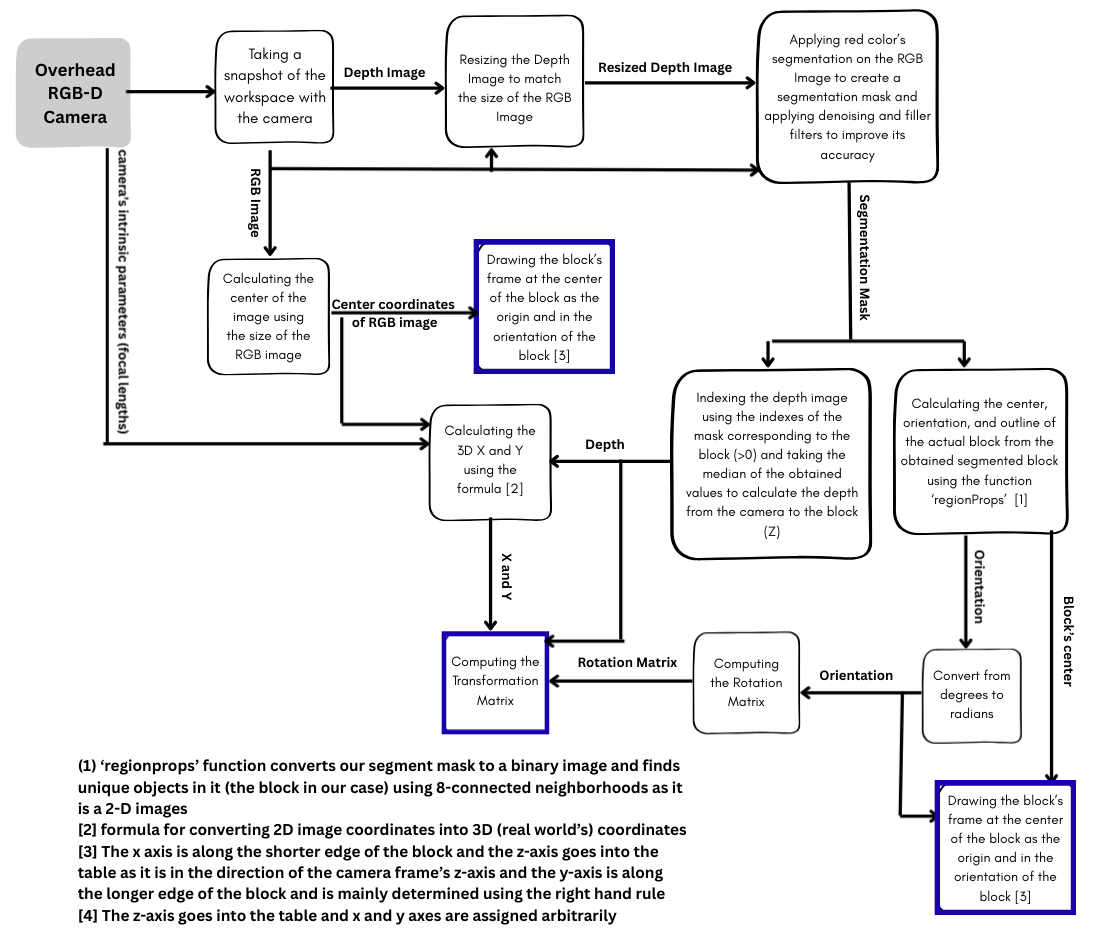

## Results:

There were 3 main test cases for the pipeline. 

i. Multiple colored blocks in ambient lighting (nominal lighting conditions)

 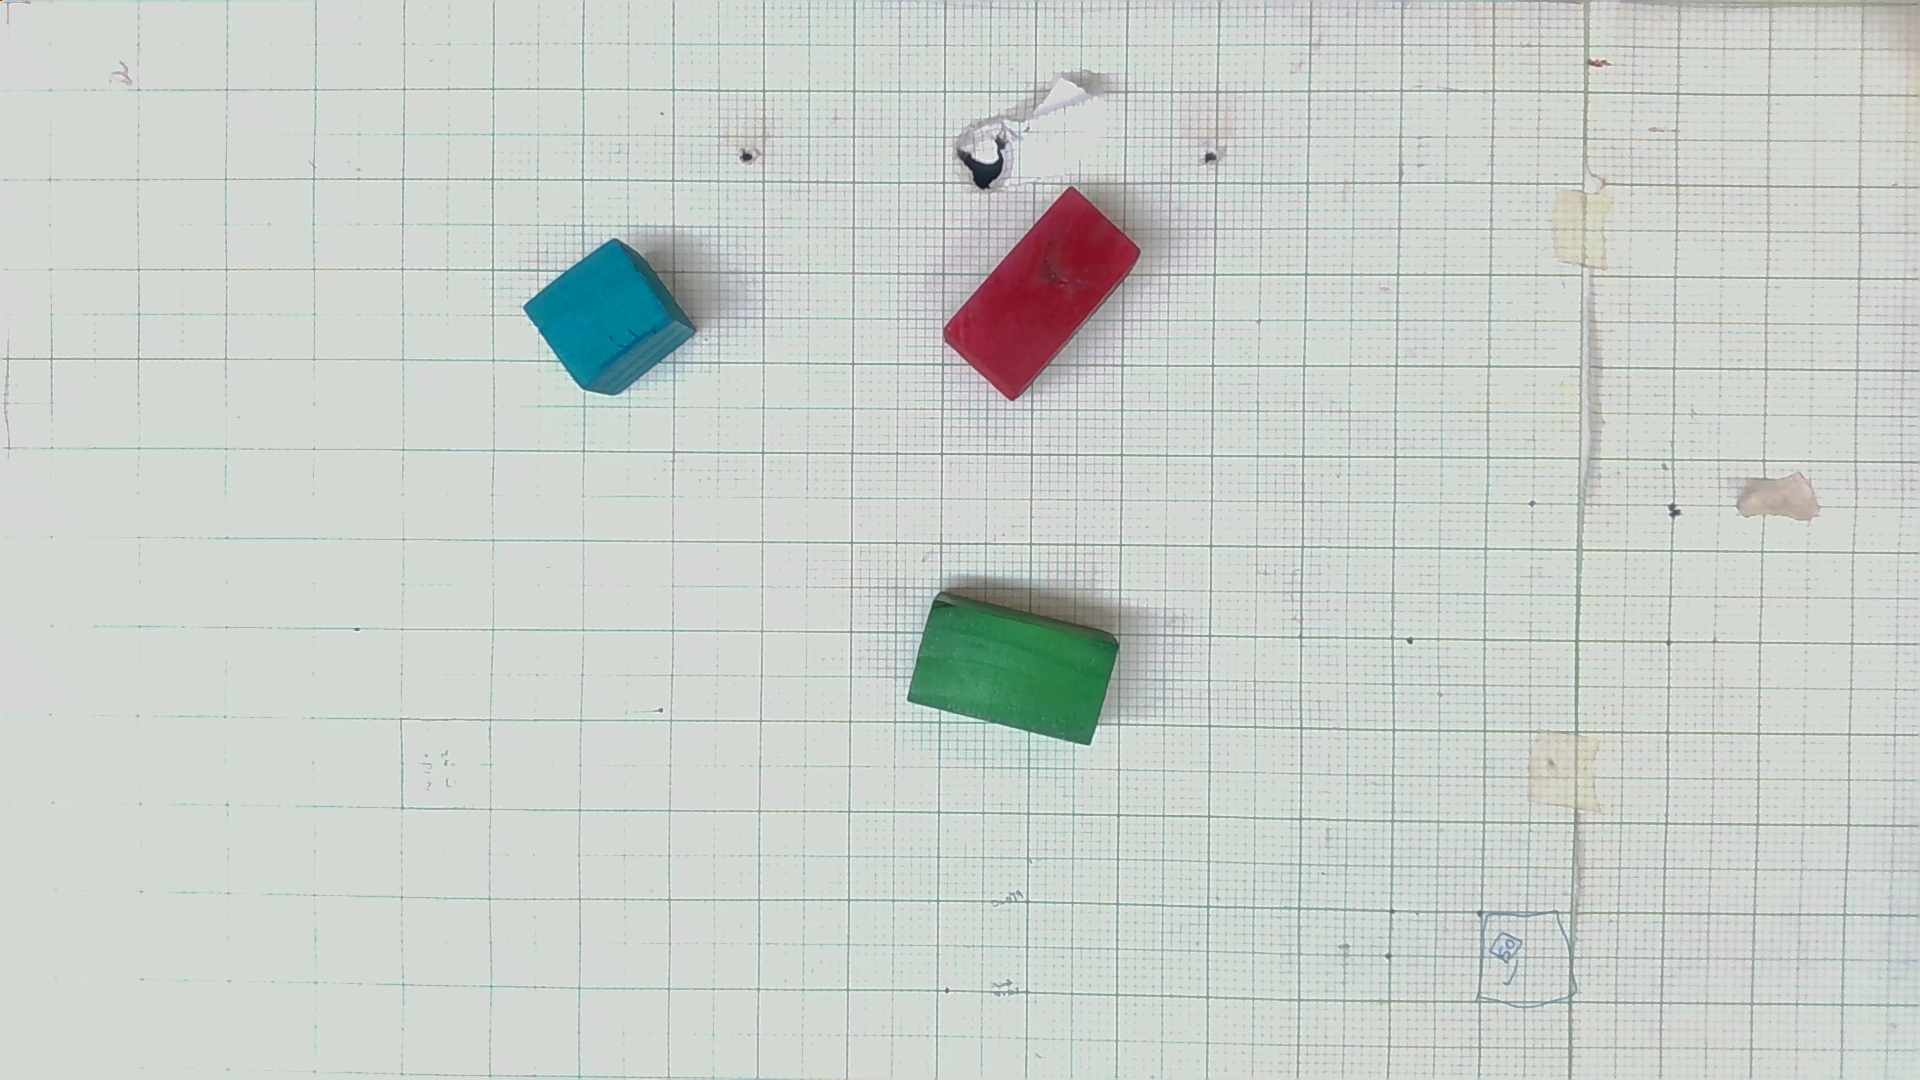

Due to the proper lighting conditions and minimized glare, the segmentation mask of the block was produced accurately. As everything built up on this mask, the rest of the paramaters and the required outputs were calculated according to the success criteria defined earlier. This shows that the pipeline works under nominal conditions and can recognize the required colored block among the others correctly. 

ii. A single red colored block under very bright lights producing significant glare on the top surface of the block

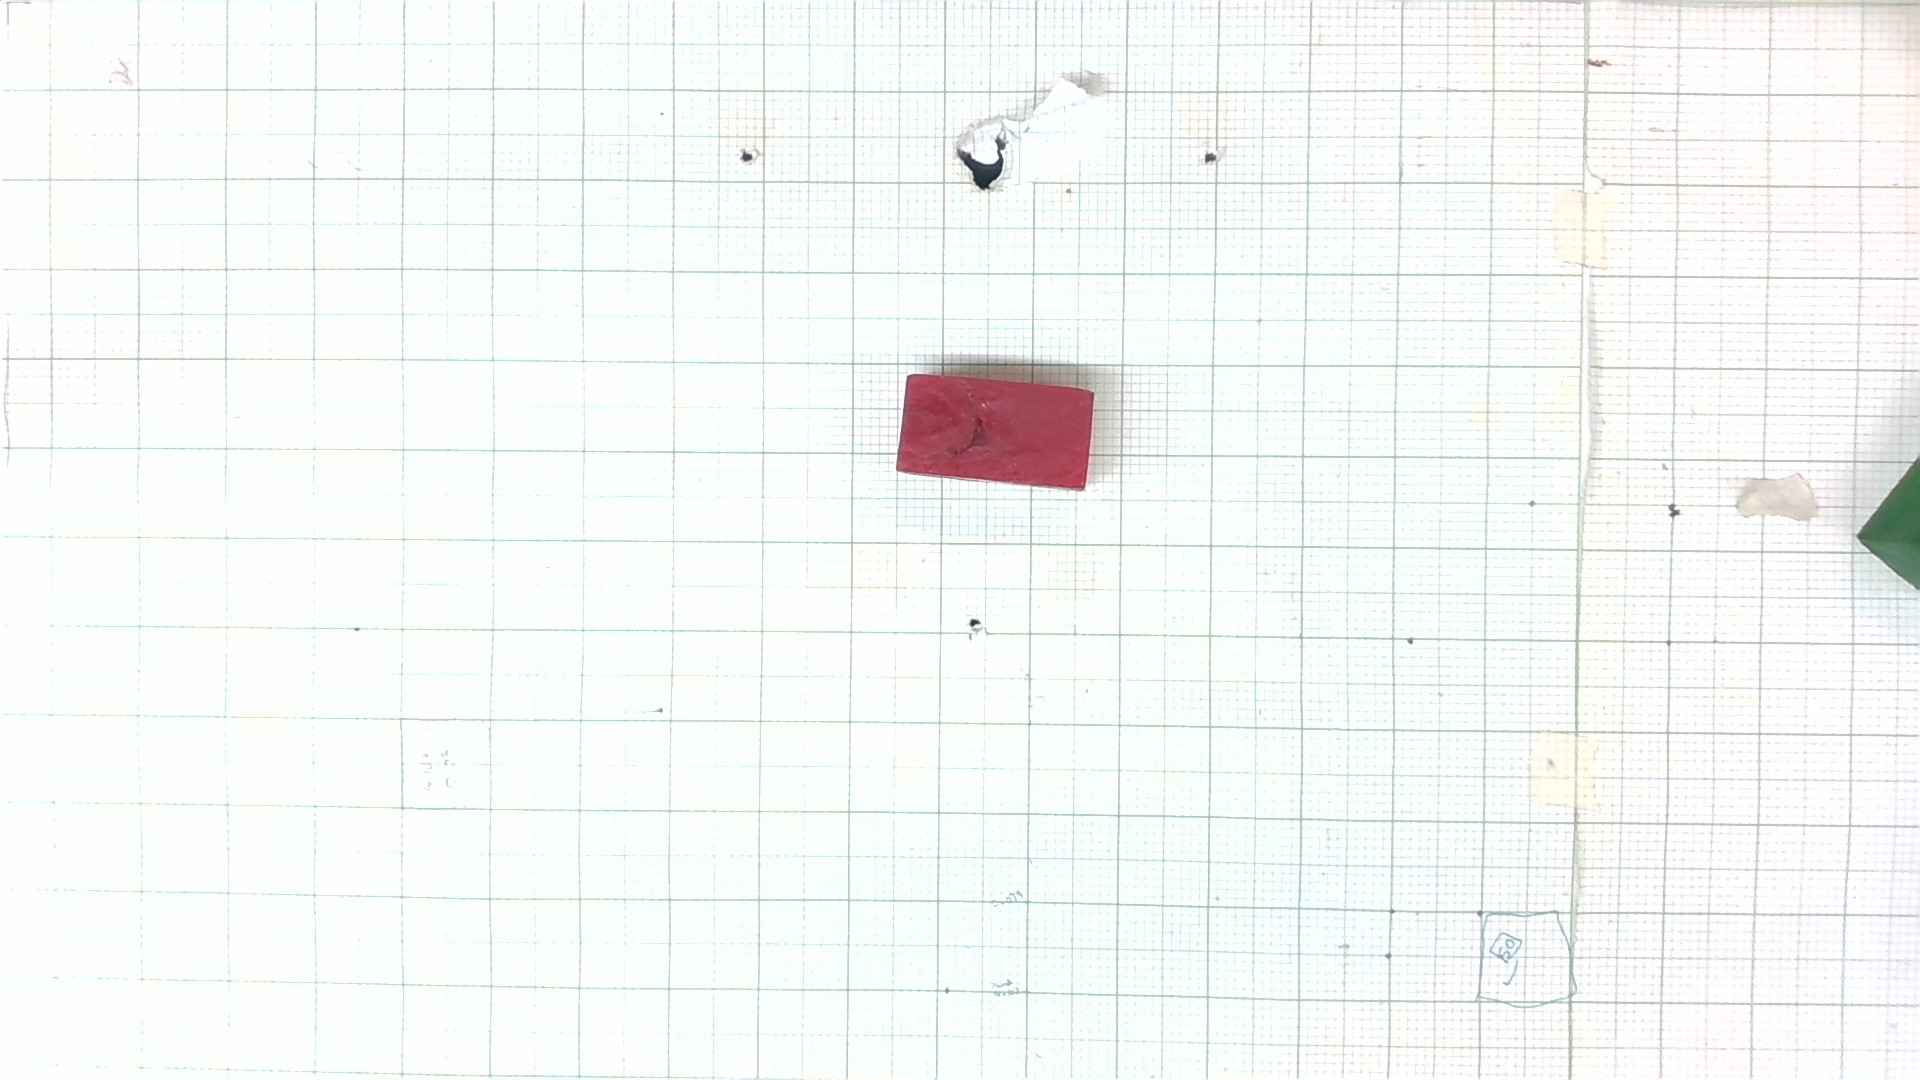

Due to the extreme lighting conditions and glare, the segmentation mask of the block was produced inaccurately. As everything built up on this mask, the rest of the paramaters and the required outputs were calculated according to this incorrect mask, leading to incorrect results. This shows that the pipeline works cannot work accurately under very bright lighting conditions. 

iii. A single red colored block of different dimensions under nominal lighting conditions

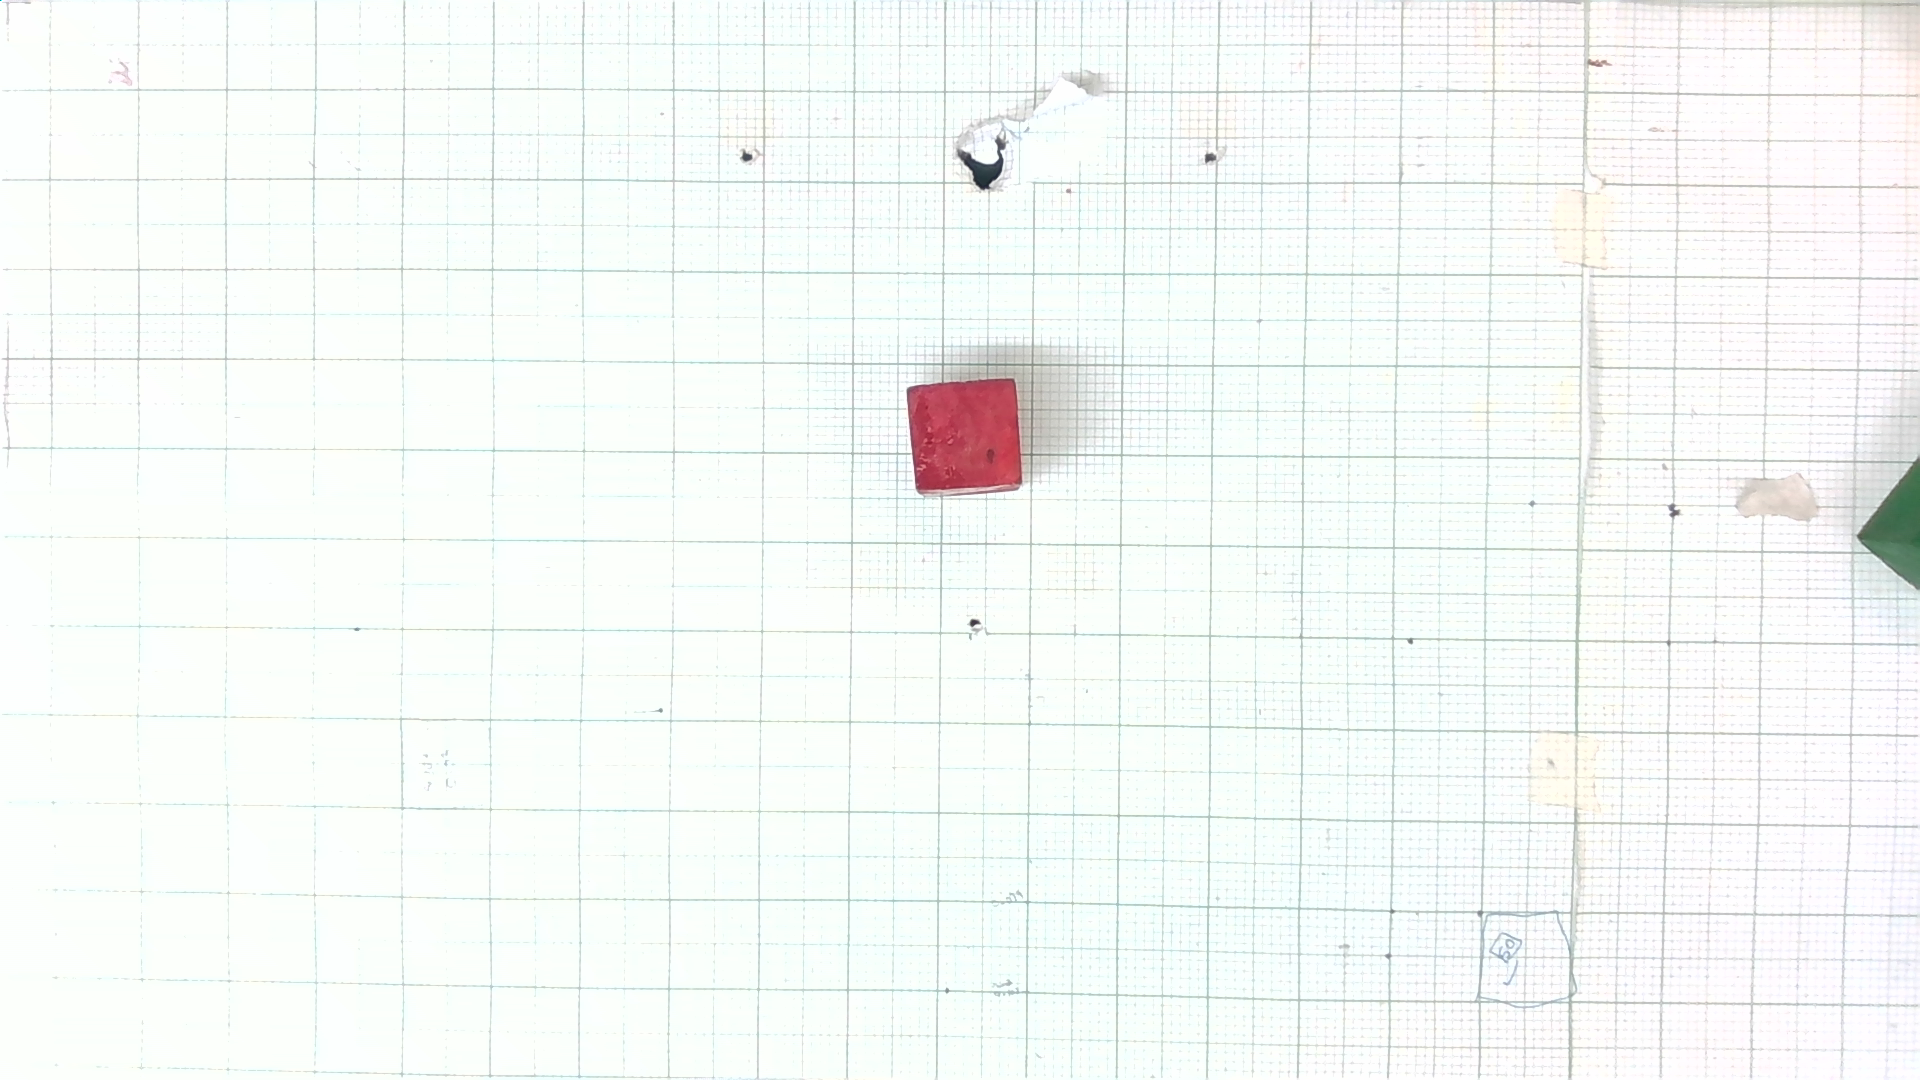

Due to the proper lighting conditions and minimized glare, the segmentation mask of the block was produced accurately. As everything built up on this mask, the rest of the paramaters and the required outputs were calculated according to the success criteria defined earlier. This shows that the pipeline works accurately for different sized blocks of the same color as well

## Code:

The segmentation masks and the results of the above test cases are shown below.

clc; clear; close all;

% Running the code for 3 test cases
rgbFiles = {'rgb_Color.png', 'rgb1_Color.png', 'rgb2_Color.png'};
depthFiles = {'Depth.mat', 'Depth1.mat', 'Depth2.mat'};

for i = 1:length(rgbFiles)
    fprintf('\n TEST CASE %d\n', i);
    
    % Loading Depth File
    tempDepth = load(depthFiles{i}); 
    fields = fieldnames(tempDepth);
    imgDepth = tempDepth.(fields{1}); 
    
    % Loading RGB File
    imgRGB = imread(rgbFiles{i});

    [rows, cols, ~] = size(imgRGB);
    if size(imgDepth, 1) ~= rows || size(imgDepth, 2) ~= cols
        imgDepth = imresize(imgDepth, [rows, cols], 'nearest');
    end

    depthData = double(imgDepth);

SEGMENTATION (RED BLOCK)

    imgLab = rgb2lab(imgRGB);
    [~, a, b] = imsplit(imgLab);

    redMask = a > 22 & b > 12; 
    redMask = imclose(redMask, strel('disk', 3));
    redMask = imfill(redMask, 'holes');
    redMask = bwareaopen(redMask, 500);
    redMask = imerode(redMask, strel('disk', 2));

DRAWING THE OUTLINE OF THE BLOCK AND GETTING ITS CENTER

    stats = regionprops(redMask, 'Centroid', 'Orientation', 'ConvexHull');

    %looks at each cluster of points and returns the index for the one with the most points (the actual block instead of noise)
    [~, index] = max(cellfun(@length, {stats.ConvexHull})); 
    s = stats(index); %stats for only the block

    hull = s.ConvexHull; %outline of the block

    % calculating the min area rectangle that fits the hull and aligns it with its orientation
    [rect_x, rect_y] = minBoundingBox(hull(:,1), hull(:,2)); 

    %calculating the center of the block by taking the mean of the four corners
    block_cx = mean(rect_x(1:4));
    block_cy = mean(rect_y(1:4));

CALCULATING THE DEPTH (Z VALUE)

    height = imgDepth(redMask > 0); 
    Z = median(height(height > 0)) * 100;

CALCULATING THE X AND Y COORDINATES

    fx = 475.27; fy = 475.27; %actual intrinsic values of the camera

    %center of the image
    cx_img = cols / 2; 
    cy_img = rows / 2; 

    X = (block_cx - cx_img) * Z / fx;
    Y = (block_cy - cy_img) * Z / fy;

CALCULATNG THETA

    theta_degrees = s.Orientation;
    theta = deg2rad(theta_degrees);

COMPUTING Rotation Matrix

    R_cb = [ cos(theta),  sin(theta), 0;
            -sin(theta),  cos(theta), 0;
             0,           0,          1];

PUTTING TOGETHER THE TRANSFORMATION MATRIX

    T_cb = [R_cb, [X; Y; Z]; 
            0, 0, 0, 1];
    fprintf('Transformation Matrix\n');
    disp(T_cb);

DRAWING THE FRAMES ON THE RGB IMAGE


 TEST CASE 1


Transformation Matrix


    0.6849    0.7287         0    7.1875
   -0.7287    0.6849         0  -20.6514
         0         0    1.0000   39.9957
         0         0         0    1.0000



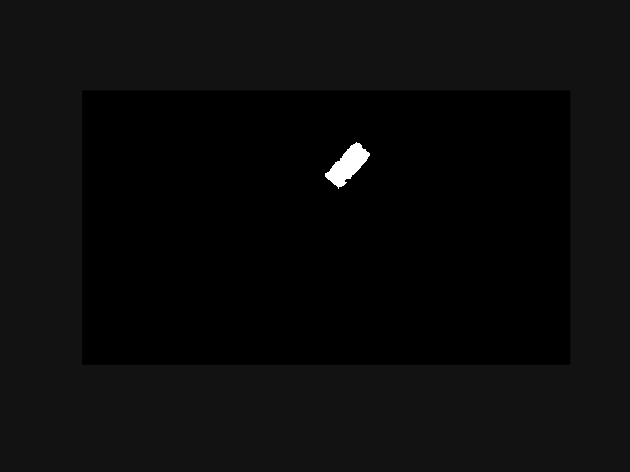

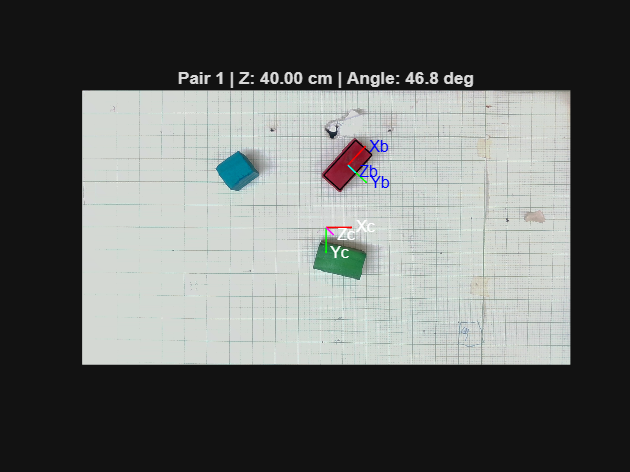


 TEST CASE 2


Transformation Matrix


    0.4603    0.8878         0    9.7230
   -0.8878    0.4603         0   -5.6313
         0         0    1.0000   40.0957
         0         0         0    1.0000



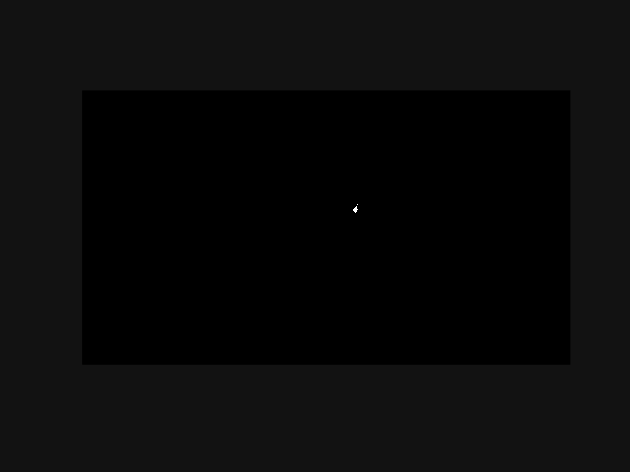

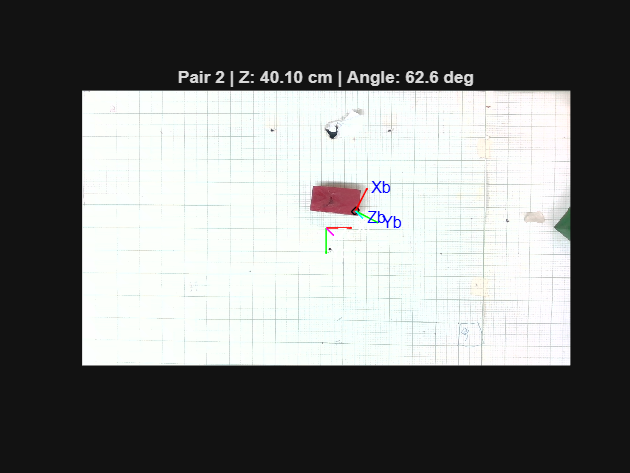


 TEST CASE 3


Transformation Matrix


    0.9354    0.3536         0    0.6988
   -0.3536    0.9354         0   -8.6734
         0         0    1.0000   40.3207
         0         0         0    1.0000



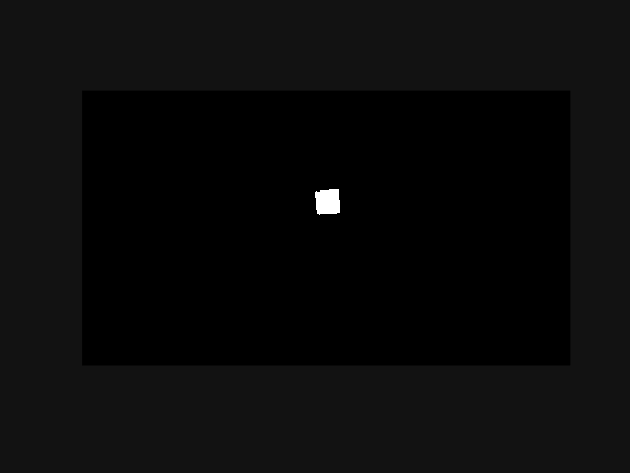

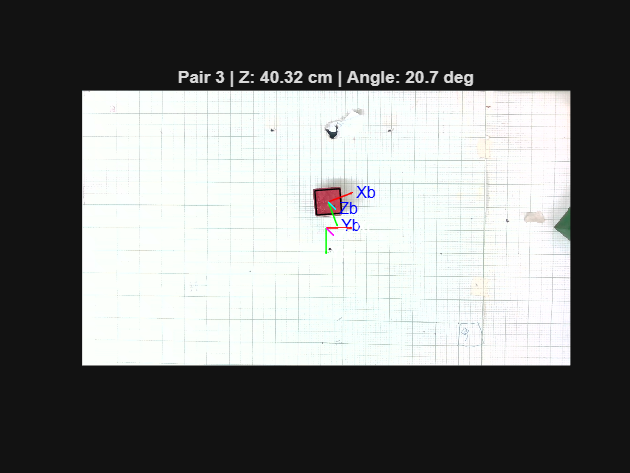

    figure;
    imshow(redMask);
    figure;
    imshow(imgRGB); hold on;
    axisLen = 100;
    zLen = axisLen * 0.4;

    % BLOCK FRAME
    plot(rect_x, rect_y, 'k', 'LineWidth', 0.5); 
    quiver(block_cx, block_cy, axisLen*cos(theta), -axisLen*sin(theta), 0, 'r', 'LineWidth', 1); 
    text(block_cx + axisLen*cos(theta), block_cy  -axisLen*sin(theta), ' Xb', 'Color', 'b');

    quiver(block_cx, block_cy, axisLen*sin(theta), axisLen*cos(theta), 0, 'g', 'LineWidth', 1);  
    text(block_cx + axisLen*sin(theta), block_cy +axisLen*cos(theta), ' Yb', 'Color', 'b');

    quiver(block_cx, block_cy, zLen*cos(pi/4), zLen*sin(pi/4), 0, 'c', 'LineWidth', 1);            
    text(block_cx + zLen*cos(pi/4), block_cy + zLen*sin(pi/4), ' Zb', 'Color', 'b');
    
    % CAMERA FRAME
    quiver(cx_img, cy_img, axisLen, 0, 0, 'r', 'LineWidth', 1); 
    text(cx_img + axisLen, cy_img, ' Xc', 'Color', 'w');

    quiver(cx_img, cy_img, 0, axisLen, 0, 'g', 'LineWidth', 1); 
    text(cx_img, cy_img + axisLen, ' Yc', 'Color', 'w');

    quiver(cx_img, cy_img, zLen*cos(pi/4), zLen*sin(pi/4), 0, 'm', 'LineWidth', 1);
    text(cx_img + zLen*cos(pi/4), cy_img + zLen*sin(pi/4), ' Zc', 'Color', 'w');

    title(sprintf('Pair %d | Z: %.2f cm | Angle: %.1f deg', i, Z, theta_degrees));
    hold off;
end

%% Helper Function
function [rx, ry] = minBoundingBox(x, y)
    hull = [x, y];
    edges = diff(hull);
    angles = atan2(edges(:,2), edges(:,1));
    angles = unique(mod(angles, pi/2));
    
    min_area = Inf;
    best_R = eye(2);
    best_rect = zeros(5,2);
    
    for i = 1:length(angles)
        R = [cos(angles(i)) sin(angles(i)); -sin(angles(i)) cos(angles(i))];
        rot_hull = (R * hull')';
        mx = min(rot_hull(:,1)); Mx = max(rot_hull(:,1));
        my = min(rot_hull(:,2)); My = max(rot_hull(:,2));
        area = (Mx - mx) * (My - my);
        if area < min_area
            min_area = area;
            best_rect = [mx my; Mx my; Mx My; mx My; mx my];
            best_R = R;
        end
    end
    final_rect = (best_R' * best_rect')';
    rx = final_rect(:,1);
    ry = final_rect(:,2);
end

## Failure Modes and Limitations:

The main failure mode and limitation of the pipeline observed was the extreme lighting condition. The case for extreme bright lighting was shown above. Below are two examples from under-lit scenarios with a change in the orientation and the position of the block, showing that the pose does not affect the results, the lighting condition does.

Example 1:

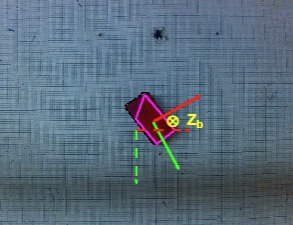

Example 2:

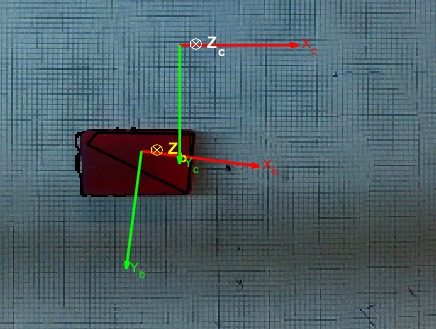

This limitation exists as the entire pipeline depends on the segmentation mask which has been defined for a specific range of the LAB values. Hence, when the lighting conditions change, the resulting LAB values would also differ leading to the defined criteria for segmentation not being met and hence producing inaccurate results. 

Though a scenaro for occlusion was not tested, it can be inferred from the above experiments that the pipeline would fail to produce accurate results in that case as well as the constructed segmentation mask would not be a represenation of the actual block in real life.

It can be concluded from the above that our pick and place system would require consistent nominal lighting conditions according to the one seen previously to operate accurately. If that cannot be ensured, the robot arm will keep reaching for the wrong places and have a different perception of the dimensions and orientation of the block than in reality,

## Next Steps:

Going forward, such solutions would have to be looked up that do not rely on a static definiton for producing segmentation masks, i.e segmentation masks should be produced using proportionality of the different LAB or RGB values instead of fixed ranges. Another solution could be to implement a pipeline that does not rely on segmentation at all, though that might not be the most achievable implementation going forward due to the limited amount of time and the possibility of extensive study for this matter.

Another step is also to introduce the segmentation of the other colored blocks so that each can be identified. 

Furthermore, a solution against occlusion also needs to be implemented as the camera  will probably keep getting blocked partially due to the robotic arm itself. One possible solution could be to use the knowledge of the actual dimensions of the blocks and retrace the partial block that is visible based on them. Further thought and work is required in this area.

Lastly, the assignment of a frame to the end-effector is also required for the computing the transformation required between it and the targeted block for the pick and place system to actually function. This would have its own challenges as the end-effector is a dynamic entity, hence the frame assignment will also have to be dynamic. And there might be instances when the end effector is not visible to the camera at all, so this needs to be taken into account as well.

Currently, I am most concerned about resolving the partial occlusion issue.